# CX 4803 - Assignment 4 - Quill Healey

## Question 1

**Firstly, let's look at the no-noise case.**

### a)


$$\Sigma_{11} = \mathbb{K} \text{, a Gram matrix of dimensions} \ n\times n  \text{, whose} \  (i^{th}, j^{th}) \ \text{entry is defined by} \ k(x_i, x_j)\  \text{for} \ \ i, j = 1, \ldots, n \\
\Sigma_{12} \ \text{is a } \ n \times N \ \text{matrix whose} \ (i^{th}, j^{th}) \ \text{entry is defined by} \ k(x_i, x_j) \ \text{for } \ i = 1, \ldots, n \ \text{and} \ j = n+1, \ldots, N\\
\Sigma_{21} = \left(\Sigma_{12}\right)^T\\
\Sigma_{22} \ \text{is a } \ N \times N \ \text{matrix whose} \ (i^{th}, j^{th}) \ \text{entry is defined by} \ k(x_i, x_j) \ \text{for } \  \ i, j = n+1, \ldots, N$$


### b)

Recall for an arbitrary, multivariate Gaussian,$\mathbf{x} \sim N(\mathbf{0}, \Sigma)$, that is broken into block matrix form:$\pmatrix{\mathbf{x_a} \cr \mathbf{x_b}} \sim N\left(\pmatrix{\mathbf{\mu_a} \cr \mathbf{\mu_b} }, \pmatrix{\Sigma_{aa} & \Sigma_{ab} \cr \Sigma_{ba} & \Sigma_{bb}}\right)$, the conditional probability $p(\mathbf{x_a}|\mathbf{x_b}) = N(\mathbf{\mu_{a|b}}, \Sigma_{a|b})$ where

 $\mathbf{\mu_{a|b}} = \mathbf{\mu_a} + \Sigma_{ab}\Sigma_{bb}^{-1}(\mathbf{x_b} - \mathbf{\mu_b}) \ \text{and} \ \Sigma_{a|b} = \Sigma_{aa} - \Sigma_{ab}\Sigma_{bb}^{-1}\Sigma_{ba}$.

Using this result we can write an equation for $p(\mathbf{\hat{y}}|\mathbf{y})$, being mindful that we will need adjust the above formulas slighly as we are looking for $p(\mathbf{x_b}|\mathbf{x_a})$, not $p(\mathbf{x_a}|\mathbf{x_b})$.

We find: $p(\mathbf{\hat{y}}|\mathbf{y}) = {N\left(\mathbf{\mu_{\hat{y}|y}}, \Sigma_{\hat{\mathbf{y}}|\mathbf{y}}\right)$, where 


$$\mathbf{\mu_{\hat{y}|y}} = \Sigma_{21}\Sigma_{11}^{-1}\mathbf{y} = \Sigma_{21}\mathbb{K}^{-1}\mathbf{y} \ \text{and} \\
\Sigma_{\mathbf{\hat{y}}|\mathbf{y}} = \Sigma_{22} - \Sigma_{21}\Sigma_{11}^{-1}\Sigma_{12} = \Sigma_{22} - \Sigma_{21}\mathbb{K}^{-1}\Sigma_{12}$$


**Now taking into account noise **$\beta^{-1}$, so that we are trying to model $\mathbf{y} = f(\mathbf{x}) + \epsilon$, corresponding to the prior $p(\mathbf{y}|\mathbf{f}) = N(\mathbf{y}|\mathbf{f}, \beta^{-1}I_n)$.

### **a1)**

(To differentiate between noise vs no noise I will add a tilde to the noise terms)


$$\tilde{\Sigma}_{11} = \mathbb{K} + \beta^{-1}I_n = \mathbf{C_n}\\
\tilde{\Sigma}_{12} = \Sigma_{12}\\
\tilde{\Sigma}_{21} = (\tilde{\Sigma}_{12})^T \\
\tilde{\Sigma}_{22} = \Sigma_{22} + \beta^{-1}I_N$$


### b1)

$p(\mathbf{\hat{y}}|\mathbf{y}) = {N\left(\mathbf{\mu_{\hat{y}|y}}, \Sigma_{\hat{\mathbf{y}}|\mathbf{y}}\right)$, where

 
$$\mathbf{\mu_{\hat{y}|y}} = \tilde{\Sigma}_{21}\tilde{\Sigma}_{11}^{-1}\mathbf{y} = \tilde{\Sigma}_{21}\mathbf{C_n}^{-1}\mathbf{y} \ \text{and} \\
\tilde{\Sigma}_{\mathbf{\hat{y}}|\mathbf{y}} = \tilde{\Sigma}_{22} - \tilde{\Sigma}_{21}\tilde{\Sigma}_{11}^{-1}\tilde{\Sigma}_{12} = \left(\Sigma_{22} + \beta^{-1}I_N\right) - \tilde{\Sigma}_{21}\mathbf{C_n}^{-1}\tilde{\Sigma}_{12}$$


## Question 2

We will generate a replica of Figure 3.9 in Bishop using GP Regression. This requires that we perform the technique when we have $n = 1, 2, 4, 25$ training data points. However, we will always use $N = 100$ prediction points in order for a curve to be drawn. Note that we will simply be writing code corresponding to Question 1 (with noise) and using a Gaussian kernel. The four plots will each include the target sine wave (green), the best estimate of the sine wave $\mathbf{\mu_{\hat{y}|y}}$ (red), as well as five samples from the GP family (blue), computed using the Cholesky decomposition to sample from the respective conditional normal distributions.

fun = @(x) sin(2*pi*x);
beta = 1e3; % inverse noise variance
s = 0.1; % kernel hyperparameter

% generate training data for n = 1, 2, 4, 25
[x1, y1] = synthetic_sinusoidal_data(1, beta);
[x2, y2] = synthetic_sinusoidal_data(2, beta);
[x3, y3] = synthetic_sinusoidal_data(4, beta);
[x4, y4] = synthetic_sinusoidal_data(25, beta);

% Generate testing data
N = 100;
xx = rand(N, 1);
xx = sort(xx);

% Compute the mu_y_hat|y and Sigma_y_hat|y corresponding to n = 1, 2,
% 4, 25
% We will use the "tic" "toc" functionality to time the inefficient version
% of the gaussian process regression function (computes the inverse of C).
tic
[cond_mu1, cond_sigma1] = ineff_gauproc_regr(1, x1, y1, N, xx, s, beta);
[cond_mu2, cond_sigma2] = ineff_gauproc_regr(2, x2, y2, N, xx, s, beta);
[cond_mu3, cond_sigma3] = ineff_gauproc_regr(4, x3, y3, N, xx, s, beta);
[cond_mu4, cond_sigma4] = ineff_gauproc_regr(25, x4, y4, N, xx, s, beta);
toc

Elapsed time is 0.020194 seconds.



% PLOTTING

% Generating the necessary sample data 

% Computing the lower cholesky factor corresponding to each training set's
% conditional covariance matrix y_hat | y
L1 = chol(cond_sigma1, "lower");
L2 = chol(cond_sigma2, "lower");
L3 = chol(cond_sigma3, "lower");
L4 = chol(cond_sigma4, "lower");

% To match Bishop's Figure 3.9 I will generate 5 samples for each training
% set of varying size
samples = []


samples =

     []



for i = 1:5
samples = [samples randn(N, 1)]
end

samples =    -1.1201
    2.5260
    1.6555
    0.3075
   -1.2571
   -0.8655
   -0.1765
    0.7914
   -1.3320
   -2.3299


samples =    -1.1201   -0.5900
    2.5260   -0.2781
    1.6555    0.4227
    0.3075   -1.6702
   -1.2571    0.4716
   -0.8655   -1.2128
   -0.1765    0.0662
    0.7914    0.6524
   -1.3320    0.3271
   -2.3299    1.0826


samples =    -1.1201   -0.5900    1.4790
    2.5260   -0.2781   -0.8608
    1.6555    0.4227    0.7847
    0.3075   -1.6702    0.3086
   -1.2571    0.4716   -0.2339
   -0.8655   -1.2128   -1.0570
   -0.1765    0.0662   -0.2841
    0.7914    0.6524   -0.0867
   -1.3320    0.3271   -1.4694
   -2.3299    1.0826    0.1922


samples =    -1.1201   -0.5900    1.4790   -1.0799
    2.5260   -0.2781   -0.8608    0.1992
    1.6555    0.4227    0.7847   -1.5210
    0.3075   -1.6702    0.3086   -0.7236
   -1.2571    0.4716   -0.2339   -0.5933
   -0.8655   -1.2128   -1.0570    0.4013
   -0.1765    0.0662   -0.2841    0.9421
    0.7914    0.6524   -0.0867    0.3005
   -1.3320    0.3271   -1.4694   -0.3731
   -2.3299    1.0826    0.1922    0.8155


samples =    -1.1201   -0.5900    1.4790   -1.0799    2.0034
    2.5260   -0.2781   -0.8608    0.1992    0.9510
    1.6555    0.4227    0.7847   -1.5210   -0.4320
    0.3075   -1.6702    0.3086   -0.7236    0.6489
   -1.2571    0.4716   -0.2339   -0.5933   -0.3601
   -0.8655   -1.2128   -1.0570    0.4013    0.7059
   -0.1765    0.0662   -0.2841    0.9421    1.4158
    0.7914    0.6524   -0.0867    0.3005   -1.6045
   -1.3320    0.3271   -1.4694   -0.3731    1.0289
   -2.3299    1.0826    0.1922    0.8155    1.4580


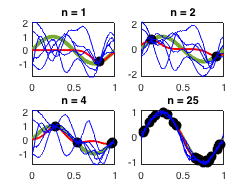


% Each subplot has the follwoing 7 overlaying plots
% 1. (green) Target function with no noise
% 2. (red) Best estimate for the test data (mean)
% 3 - 7. (blue) 5 "family" curves. Sampled from N(0, I) and then
%   transformed using the lower triangular cholesky factor (derived from
%   conditioned covariance matrix y_hat | y) and conditioned mean

% n = 1
clf
subplot(2, 2, 1)
plot(xx, fun(xx), '-', Color = [0.4660 0.6740 0.1880], LineWidth= 4)
hold on
plot(xx, cond_mu1, '-', Color='red', LineWidth = 2);
plot(x1, y1, 'ko', Color = 'black', LineWidth = 4)
for z = samples
plot(xx, L1*z + cond_mu1, '-', Color = 'blue');
end
title('n = 1')

% n = 2
subplot(2, 2, 2)
plot(xx, fun(xx), '-', Color = [0.4660 0.6740 0.1880], LineWidth= 4);
hold on
plot(xx, cond_mu2, '-', Color='red', LineWidth = 2);
plot(x2, y2, 'ko', Color = 'black', LineWidth = 4)
for z = samples
plot(xx, L2*z + cond_mu2, '-', Color = 'blue');
end
title('n = 2')

% n = 4
subplot(2, 2, 3)
plot(xx, fun(xx), '-', Color = [0.4660 0.6740 0.1880], LineWidth= 4);
hold on
plot(xx, cond_mu3, '-', Color='red', LineWidth = 2);
plot(x3, y3, 'ko', Color = 'black', LineWidth = 4)
for z = samples
plot(xx, L3*z + cond_mu3, '-', Color = 'blue');
end
title('n = 4')

% n = 25
subplot(2, 2, 4)
plot(xx, fun(xx), '-', Color = [0.4660 0.6740 0.1880], LineWidth= 4);
hold on
plot(xx, cond_mu4, '-', Color='red', LineWidth = 2);
plot(x4, y4, 'ko', Color = 'black', LineWidth = 4)
for z = samples
plot(xx, L4*z + cond_mu4, '-', Color = 'blue');
end
title('n = 25')

## Question 3

The following code blocks consists of two components. 

Firstly, we will once again compute the conditional parameters corresponding to each $n = 1, 2, 4, 25$ training datasets using GP regression. However, we will use the "gauproc_regr" function, as opposed to "ineff_gauproc_regr," which computes $C^{-1}y$ using the lower traingular Cholesky factor (as detailed in the question prompt). I time these function calls, and comparing the runtime with that of the equivalent code above we see that the efficient code does appear to run somewhat faster, particularly upon running this script for the first time post-Matlab-boot-up. I'm sure that we would see a larger speed increase if we were to build larger matrrices.

Secondly, we will output the Figure 3.9 plot corresponding to GP regression with $n = 4$ as a sanity check that our faster computational method does not lead to any inaccuracies.  

tic

[cond_mu1, cond_sigma1] = gauproc_regr(1, x1, y1, N, xx, s, beta);
[cond_mu2, cond_sigma2] = gauproc_regr(2, x2, y2, N, xx, s, beta);
[cond_mu3, cond_sigma3] = gauproc_regr(4, x3, y3, N, xx, s, beta);
[cond_mu4, cond_sigma4] = gauproc_regr(25, x4, y4, N, xx, s, beta);

toc

Elapsed time is 0.012992 seconds.


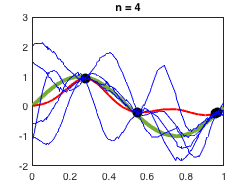


L3 = chol(cond_sigma3, "lower");

clf
plot(xx, fun(xx), '-', Color = [0.4660 0.6740 0.1880], LineWidth= 4);
hold on
plot(xx, cond_mu3, '-', Color='red', LineWidth = 2);
plot(x3, y3, 'ko', Color = 'black', LineWidth = 4)
for z = samples
plot(xx, L3*z + cond_mu3, '-', Color = 'blue');
end
title('n = 4')

## Question 4

I will give a quick overview of the following code. Firstly, we will break the given data into training and testing partitions according to the popular 80/20 split. From here we will run our previously implemented GP regression function with $\beta = 1e3$ and $s = 0.1$, the two values used most commonly in this class so far. Before attempting to make the desired point predictions, we will first attempt to reduce the test MSE by choosing varying values for $\beta$ and $s$. Once we find best guesses we will make the point predictions.

(Albiet these best guesses were not chosen very scientifically and it would be interesting to apply Bishop page 311, or something similar to SGD to help choose $s$. Of course, $\beta$ is chosen by nature so we would need to either build another GP to model it, or another statistical measure.)

A = importdata("a4data")

A =    -1.8389   -0.5316  -73.6451
   -1.3228    2.0871  -70.9887
    3.1506    1.2024  -71.1954
    0.6317    1.7342  -48.6529
   -0.1603    4.4674  -39.1770
    0.9042    4.5410  -31.9743
   -2.1163    6.4632  -21.5734
    0.4916    5.8321   -5.7056
    0.8266    7.9598   17.8668
   -1.8912    7.7702   35.8260


cv = cvpartition(length(A), 'HoldOut', .2)

cv = Hold-out cross validation partition
   NumObservations: 705
       NumTestSets: 1
         TrainSize: 564
          TestSize: 141

x_train = A(cv.training, 1:2);
x_test = A(cv.test, 1:2);
y_train = A(cv.training, 3);
y_test = A(cv.test, 3);
n = cv.TrainSize;
N = cv.TestSize;

% Let's start with our typical s and beta values
s = .1;
beta = 1e3;

[cond_mu, cond_sigma] = gauproc_regr(n, x_train, y_train, N, x_test, s, beta);

% Compute MSE with held out test data to determine our model accuracy
% (albiet noting that MSE is far from an all-inclusive test)
MSE = (1/N) * sum((y_test - cond_mu).^2)

MSE = 4.3233e+03


% Sample variance
sample_var = 1 / (n - 1) * sum((y_train - mean(y_train)).^2)

sample_var = 4.5116e+03


% Test various values for beta and s, trying to reduce MSE_te
mu_best = cond_mu

mu_best =   -48.5441
    0.0000
    0.0000
    2.3927
    0.0000
    0.0000
    0.0001
   -0.0000
   -0.0007
    0.0000


cov_best = cond_sigma

cov_best =     0.3481   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000         0         0    0.0000         0         0         0         0         0         0         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000    1.0010    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

for i_s = [0.01, 0.05, 0.1, 0.3, 0.5, .7, 1, 1.5, 2]
for i_b = [1e3, 1e2, 1, 4, 10, 15, 20, 50 1/sample_var]
    [cond_mu, cond_sigma] = gauproc_regr(n, x_train, y_train, N, x_test, i_s, i_b);
    mse = (1/N) * sum((y_test - cond_mu).^2);
    if (mse < MSE)
        MSE = mse;
        mu_best = cond_mu;
        cov_best = cond_sigma;
        s = i_s
        beta = i_b
    end
end
end

s = 0.3000

beta = 1000

s = 0.5000

beta = 1000

s = 0.5000

beta = 100

s = 0.5000

beta = 4

s = 0.5000

beta = 10

s = 0.7000

beta = 100

s = 0.7000

beta = 1

s = 0.7000

beta = 4

s = 1

beta = 1

s = 1.5000

beta = 1

s = 2

beta = 1


% Display the best s and beta values, along with the corresponding MSE
disp(MSE);

  709.6954



disp(s);

     2



disp(beta);

     1



% Calculate R squared
SSTO = sum((y_test - mean(y_test)).^2)

SSTO = 6.3373e+05

SSE = sum((y_test - mu_best).^2)

SSE = 1.0007e+05


Rsq = 1 - SSE/SSTO

Rsq = 0.8421

disp(Rsq)

    0.8421



% Compute our desired point estimates
x_4 = [30 30; 25 5; 4 4]

x_4 =     30    30
    25     5
     4     4


[cond_mu_y4, cond_sigma_y4] = gauproc_regr(n, x_train, y_train, 3, x_4, s, beta)

cond_mu_y4 =    56.4318
   -0.8615
   61.1062


cond_sigma_y4 =     1.3854   -0.0000   -0.0000
   -0.0000    1.1598    0.0000
   -0.0000    0.0000    1.1956


disp(cond_mu_y4)

   56.4318
   -0.8615
   61.1062



After running our code we get the following results:

Best "parameter" values:


$$s = 2\\\beta=1$$


Corresponding:


$$MSE = 709.6954\\
R^2 = 0.8421\\
\hat{f}(30, 30) = 56.4318\\
\hat{f}(25, 5) = -0.8615\\
\hat{f}(4, 4) = 61.1062$$
 

While the R squared value is rather good, I am somewhat doubtful of the accuracy of our point estimates, if not for the fact of how un-scientifically $s$ was chosen, and that I did not utilize a statistical tool to find $\beta$. $\beta = 1$ is particularly suspicious as it implies $\sigma^2 = 1$, which certainly does not correspond with the sample variance that was earlier computed.

## Local Helper Functions

function [x, y] = synthetic_sinusoidal_data(n, beta)
% SYNTHETIC_SINUSOIDAL_DATA    Generate n samples from a sine wave
%   [X, Y] = SYNTHETIC_SINUSOIDAL_DATA(n, beta) generates n x values ~ U[0,
%   1] and corresponding values from a sin function with noise beta^-1
    x = rand(n, 1);
    y = sin(2*pi*x) + sqrt(1/beta) * randn(n, 1);
end

function cov_matrix = cov_matrix_calc(n1, n2, x1, x2, s)
% COV_MATRIX_CALC    Returns a covariance matrix whose generator is a
% Gaussian kernel
%   COV_MATRIX = COV_MATRIX_CALC(n1, n2, x1, x2, x) calculates and returns
%   a n1 x n2 covariance matrix whose (ith, jth) value corresponds to
%   k(x1j, x2i) for j = 1:n1 and i = 1:n2. The kernel function is Gaussian
%   with hyperparamter s. Note that x1 and x2 can be vectors as the 2-norm
%   is used.
    cov_matrix = zeros(n1, n2);
    for j = 1:n1
    for i = 1:n2
        cov_matrix(j, i) = exp(-0.5/(s^2) * sum((x1(j, :) - x2(i, :)).^2));
    end
    end
end

function w = compute_C_y(C, y)
% COMUTE_C_Y    Computes the term C^{-1}y using the Cholesky Factorization
% of C. Please ensure that C is a positive-diagonal, symmetric matrix.
%   W = COMUTE_C_Y(C, y) Returns the value C^{-1}y
    L = chol(C, 'lower');
    L_inv = inv(L);
    v = L_inv * y;
    w = L_inv' * v;
end

function [cond_mu, cond_cov] = ineff_gauproc_regr(n, x_tr, y_tr, N, x_te, s, beta)
% INEFF_GAUPROC_REGR   Returns mu_y_hat|h and Sigma_y_hat|y, found by using
% GP regression with a Gaussian kernel and an inefficient calculation technique for
% C^{-1}y.
%   [COND_MU, COND_COV] = INEFF_GAUPROC_REGR(n, x_tr, y_tr, N, x_te, s,
%   beta) computes the two respective parameters for the posterior
%   distribution N_y_te|y_tr, where the GP regression used n training data
%   points, x_tr, to calculate the generator covariance matrix, which is
%   then used to build a linear combination of y_tr along with the N test
%   points, x_te, that we wish to compute. "s" is the hyperparameter for
%   the kernel function while beta is the inverse noise observed in the
%   target data.
    C = cov_matrix_calc(n, n, x_tr, x_tr, s) + 1/beta * eye(n);
    sigma_21 = cov_matrix_calc(N, n, x_te, x_tr, s);
    Sigma_22 = cov_matrix_calc(N, N, x_te, x_te, s) + 1/beta * eye(N);
    
    C_inv = inv(C);
    cond_mu = sigma_21 * C_inv * y_tr;
    cond_cov = Sigma_22 - sigma_21 * (C\sigma_21');
end

function [cond_mu, cond_cov] = gauproc_regr(n, x_tr, y_tr, N, x_te, s, beta)
% GAUPROC_REGR   Returns mu_y_hat|h and Sigma_y_hat|y, found by using
% GP regression with a Gaussian kernel and an efficient calculation technique for
% C^{-1}y.
%   [COND_MU, COND_COV] = INEFF_GAUPROC_REGR(n, x_tr, y_tr, N, x_te, s,
%   beta) computes the two respective parameters for the posterior
%   distribution N_y_te|y_tr, where the GP regression used n training data
%   points, x_tr, to calculate the generator covariance matrix, which is
%   then used to build a linear combination of y_tr along with the N test
%   points, x_te, that we wish to compute. "s" is the hyperparameter for
%   the kernel function while beta is the inverse noise observed in the
%   target data.
    C = cov_matrix_calc(n, n, x_tr, x_tr, s) + 1/beta * eye(n);
    sigma_21 = cov_matrix_calc(N, n, x_te, x_tr, s);
    Sigma_22 = cov_matrix_calc(N, N, x_te, x_te, s) + 1/beta * eye(N);
    
    cond_mu = sigma_21 * compute_C_y(C, y_tr);
    cond_cov = Sigma_22 - sigma_21 * compute_C_y(C, sigma_21');
end